### Funciones AND, OR, NOR y  xOR

%Empezamos añadiendo el path a las funciones de activación 
addpath("G:\Mi unidad\MCC\Primer Semestre\Inteligencia artificial\Codigos\Funciones de activacion");

### Operador AND

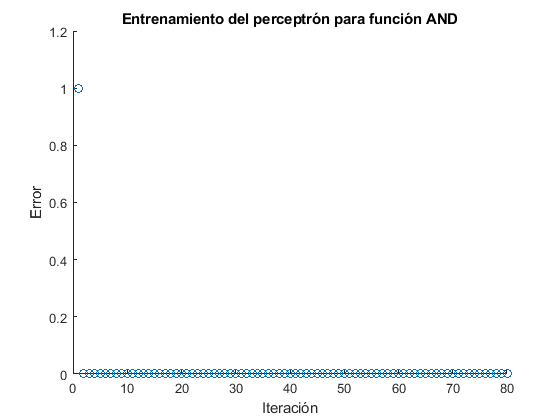

%Creamos el perceptrón 
perceptron = Perceptron(1,2);
%Los datos de entrenamiento 
trainingData = [0 0 1 1; 0 1 0 1];
trainingResults = [0,0,0,1];
epochs = 20;
[perceptron, errorData] = perceptron.train(trainingData,trainingResults,epochs);

figure()
hold on 
title('Entrenamiento del perceptrón para función AND')
plot(1:length(errorData),errorData,'o');
xlabel('Iteración')
ylabel('Error')
ylim([0,1.2])
xlim([0,length(errorData)])
hold off

% Tabla resultante de la función AND
firstEntry = trainingData(1,:)';
secondEntry = trainingData(2,:)';

results = arrayfun(@(x,y) perceptron.compute([x;y]),firstEntry,secondEntry);
T = table(firstEntry,secondEntry,results,'VariableNames',{'x','y','x AND y'})

T = 4×3 table
    x    y    x AND y
    _    _    _______

    0    0       0   
    0    1       0   
    1    0       0   
    1    1       1   


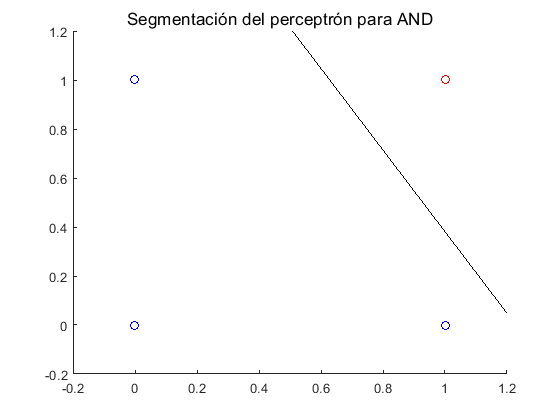

x = linspace(-1.2,1.2,1000);
y = -(perceptron.W(1)/perceptron.W(2))*x -perceptron.b/perceptron.W(2);

figure()
sgtitle('Segmentación del perceptrón para AND')
hold on 
for i = 1:size(trainingData,2)
    point = trainingData(:,i);
    if(trainingResults(i) == 1)
        plot(point(1),point(2),'o','color','red')
    else
        plot(point(1),point(2),'o','color','blue')
    end
end
%Se traza la linea
plot(x,y,'color','black')
xlim([-0.2,1.2])
ylim([-0.2,1.2])
hold off

### Operador OR

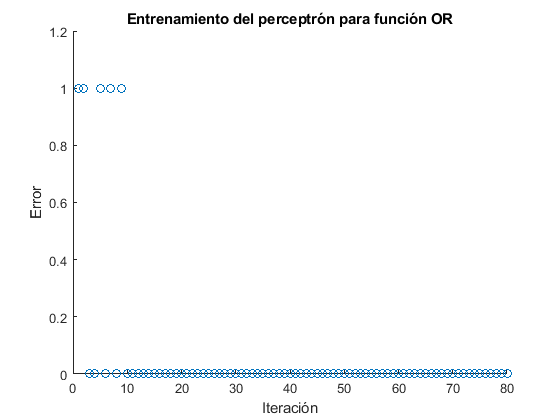

%Nuevamente armamos un perceptrón con 1 neurona y dos entradas
perceptron = Perceptron(1,2);
trainingData = [0 0 1 1; 0 1 0 1];
trainingResults = [0,1,1,1];
epochs = 20;
[perceptron, errorData] = perceptron.train(trainingData,trainingResults,epochs);

figure()
hold on 
title('Entrenamiento del perceptrón para función OR')
plot(1:length(errorData),errorData,'o');
xlabel('Iteración')
ylabel('Error')
ylim([0,1.2])
xlim([0,length(errorData)])
hold off

% Tabla resultante de la función OR
firstEntry = trainingData(1,:)';
secondEntry = trainingData(2,:)';

results = arrayfun(@(x,y) perceptron.compute([x;y]),firstEntry,secondEntry);
T = table(firstEntry,secondEntry,results,'VariableNames',{'x','y','x OR y'})

T = 4×3 table
    x    y    x OR y
    _    _    ______

    0    0      0   
    0    1      1   
    1    0      1   
    1    1      1   


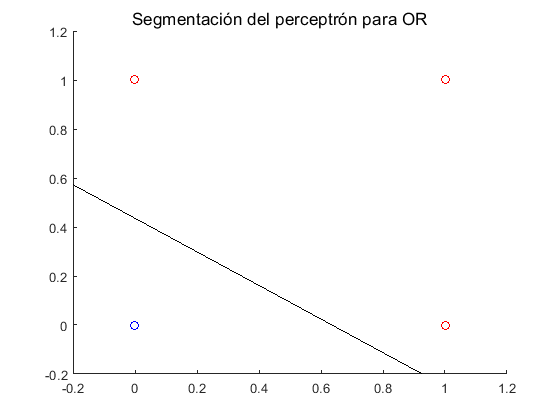

x = linspace(-1.2,1.2,1000);
y = -(perceptron.W(1)/perceptron.W(2))*x -perceptron.b/perceptron.W(2);

figure()
sgtitle('Segmentación del perceptrón para OR')
hold on 
for i = 1:size(trainingData,2)
    point = trainingData(:,i);
    if(trainingResults(i) == 1)
        plot(point(1),point(2),'o','color','red')
    else
        plot(point(1),point(2),'o','color','blue')
    end
end
%Se traza la linea
plot(x,y,'color','black')
xlim([-0.2,1.2])
ylim([-0.2,1.2])
hold off

### Operador NOR

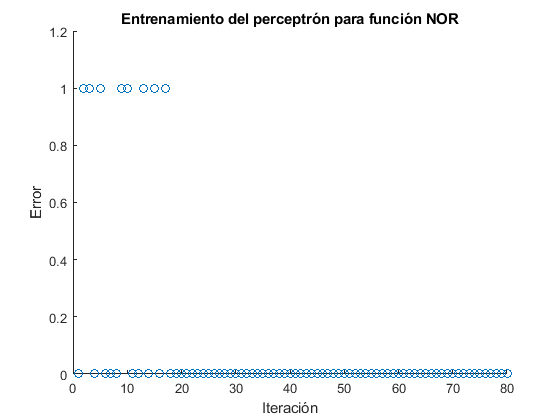

perceptron = Perceptron(1,2);
trainingData = [0 0 1 1; 0 1 0 1];
trainingResults = [1,0,0,0];
epochs = 20;
[perceptron, errorData] = perceptron.train(trainingData,trainingResults,epochs);

figure()
hold on 
title('Entrenamiento del perceptrón para función NOR')
plot(1:length(errorData),errorData,'o');
xlabel('Iteración')
ylabel('Error')
ylim([0,1.2])
xlim([0,length(errorData)])
hold off

% Tabla resultante de la función NOR
firstEntry = trainingData(1,:)';
secondEntry = trainingData(2,:)';

results = arrayfun(@(x,y) perceptron.compute([x;y]),firstEntry,secondEntry);
T = table(firstEntry,secondEntry,results,'VariableNames',{'x','y','x NOR y'})

T = 4×3 table
    x    y    x NOR y
    _    _    _______

    0    0       1   
    0    1       0   
    1    0       0   
    1    1       0   


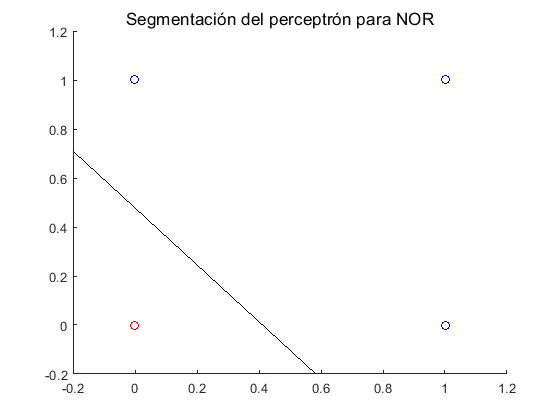

x = linspace(-1.2,1.2,1000);
y = -(perceptron.W(1)/perceptron.W(2))*x -perceptron.b/perceptron.W(2);

figure()
sgtitle('Segmentación del perceptrón para NOR')
hold on 
for i = 1:size(trainingData,2)
    point = trainingData(:,i);
    if(trainingResults(i) == 1)
        plot(point(1),point(2),'o','color','red')
    else
        plot(point(1),point(2),'o','color','blue')
    end
end
%Se traza la linea
plot(x,y,'color','black')
xlim([-0.2,1.2])
ylim([-0.2,1.2])
hold off

### Operación xOR

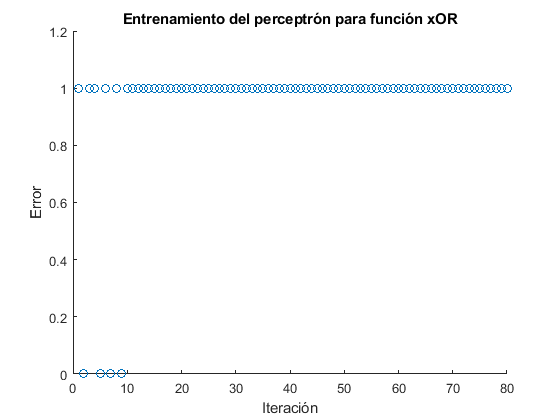

perceptron = Perceptron(1,2);
trainingData = [0 0 1 1; 0 1 0 1];
trainingResults = [0,1,1,0];
epochs = 20;
[perceptron, errorData] = perceptron.train(trainingData,trainingResults,epochs);

figure()
hold on 
title('Entrenamiento del perceptrón para función xOR')
plot(1:length(errorData),errorData,'o');
xlabel('Iteración')
ylabel('Error')
ylim([0,1.2])
xlim([0,length(errorData)])
hold off

% Tabla resultante de la función xOR
firstEntry = trainingData(1,:)';
secondEntry = trainingData(2,:)';

results = arrayfun(@(x,y) perceptron.compute([x;y]),firstEntry,secondEntry);
T = table(firstEntry,secondEntry,results,'VariableNames',{'x','y','x xOR y'})

T = 4×3 table
    x    y    x xOR y
    _    _    _______

    0    0       1   
    0    1       1   
    1    0       0   
    1    1       0   


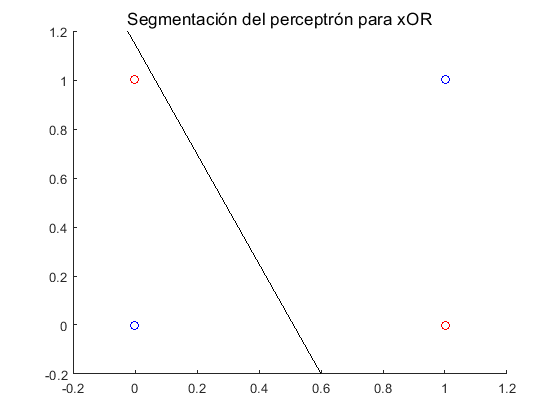

x = linspace(-1.2,1.2,1000);
y = -(perceptron.W(1)/perceptron.W(2))*x -perceptron.b/perceptron.W(2);

figure()
sgtitle('Segmentación del perceptrón para xOR')
hold on 
for i = 1:size(trainingData,2)
    point = trainingData(:,i);
    if(trainingResults(i) == 1)
        plot(point(1),point(2),'o','color','red')
    else
        plot(point(1),point(2),'o','color','blue')
    end
end
%Se traza la linea
plot(x,y,'color','black')
xlim([-0.2,1.2])
ylim([-0.2,1.2])
hold off

Vemos que para el caso de xOR el error no se vuelve cero como ocurría en el caso de las funciones lógicas anteriores, La razón de esto es que no hay linea que podamos colocar para segmentar los resultados de esta función, en la forma en que se había realizado para las demás.. La demostración gráfica sería  justamente la que se ha incluido en la figura anterior. generalmente en la literatura cuando se aborda este caso se suele decir que xOR no es lineal.

** AND 3 salidas**

Para este caso se estarán usando 3 neuronas distintas y dos entradas 

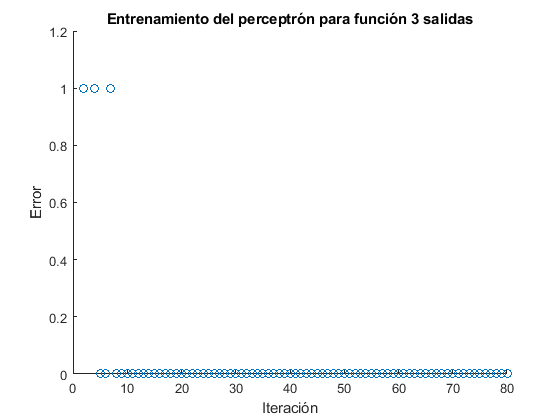

%Definimos nuestro perceptron 
perceptron = Perceptron(3,2);
%Perfecto, ahora los datos de entrenamiento 
trainingData = [0,0,1,1;0,1,0,1];
solutions =[0,0,1,1; 0,1,0,1;0,0,0,1];
%Entrenamos el perceptrón
epochs = 20;
[perceptron, errorData] = perceptron.train(trainingData,solutions,epochs);
%
figure()
hold on 
title('Entrenamiento del perceptrón para función 3 salidas')
plot(1:length(errorData),errorData,'o');
xlabel('Iteración')
ylabel('Error')
ylim([0,1.2])
xlim([0,length(errorData)])
hold off

%Probemos para las distintas entradas
disp(perceptron.compute([0;0]))

     0
     0
     0



disp(perceptron.compute([0;1]))

     0
     1
     0



disp(perceptron.compute([1;0]))

     1
     0
     0



disp(perceptron.compute([1;1]))

     1
     1
     1



### OR de 3 salidas

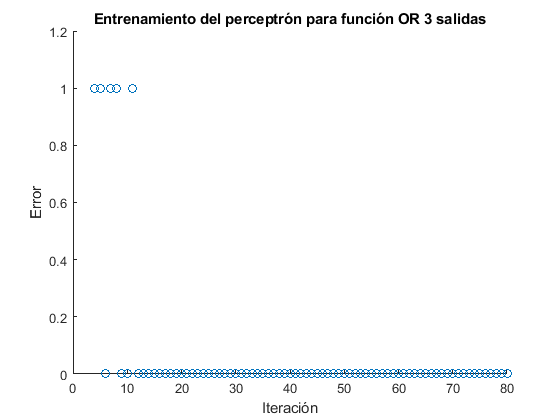

%Definimos nuestro perceptron 
perceptron = Perceptron(3,2);
%Perfecto, ahora los datos de entrenamiento 
trainingData = [0,0,1,1;0,1,0,1];
solutions =[0,0,1,1; 0,1,0,1;0,1,1,1];
%Entrenamos el perceptrón
epochs = 20;
[perceptron, errorData] = perceptron.train(trainingData,solutions,epochs);
%
figure()
hold on 
title('Entrenamiento del perceptrón para función OR 3 salidas')
plot(1:length(errorData),errorData,'o');
xlabel('Iteración')
ylabel('Error')
ylim([0,1.2])
xlim([0,length(errorData)])
hold off

disp(perceptron.compute([0;0]));

     0
     0
     0



disp(perceptron.compute([0;1]));

     0
     1
     1



disp(perceptron.compute([1;0]));

     1
     0
     1



disp(perceptron.compute([1;1]));

     1
     1
     1



### NOR de 3 salidas

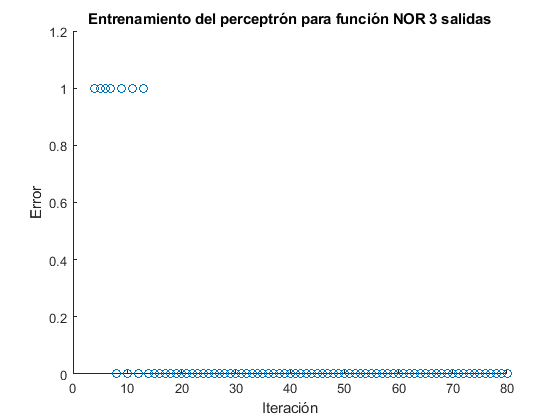

%Definimos nuestro perceptron 
perceptron = Perceptron(3,2);
%Perfecto, ahora los datos de entrenamiento 
trainingData = [0,0,1,1;0,1,0,1];
solutions =[0,0,1,1; 0,1,0,1;1,0,0,0];
%Entrenamos el perceptrón
epochs = 20;
[perceptron, errorData] = perceptron.train(trainingData,solutions,epochs);
%
figure()
hold on 
title('Entrenamiento del perceptrón para función NOR 3 salidas')
plot(1:length(errorData),errorData,'o');
xlabel('Iteración')
ylabel('Error')
ylim([0,1.2])
xlim([0,length(errorData)])
hold off

disp(perceptron.compute([0;0]));

     0
     0
     1



disp(perceptron.compute([0;1]));

     0
     1
     0



disp(perceptron.compute([1;0]));

     1
     0
     0



disp(perceptron.compute([1;1]));

     1
     1
     0



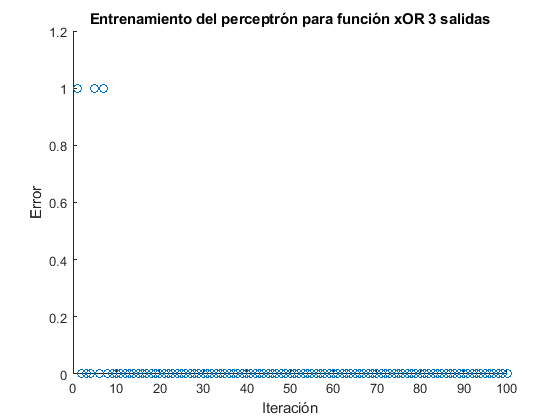

%Definimos nuestro perceptron 
perceptron = Perceptron(1,3);
%Perfecto, ahora los datos de entrenamiento 
trainingData = [0,0,1,1,1; 0,1,1,1,0; 0,0,0,1,0];
solutions =[0,1,1,1,0];
%Entrenamos el perceptrón
epochs = 20;
[perceptron, errorData] = perceptron.train(trainingData,solutions,epochs);
%
figure()
hold on 
title('Entrenamiento del perceptrón para función 3 salidas')
plot(1:length(errorData),errorData,'o');
xlabel('Iteración')
ylabel('Error')
ylim([0,1.2])
xlim([0,length(errorData)])
hold off

disp(perceptron.compute([0;0;0]))

     0



disp(perceptron.compute([0;0;1]))

     1



disp(perceptron.compute([0;1;0]))

     1



disp(perceptron.compute([1;1;0]))

     1



disp(perceptron.compute([1;1;1]))

     1



disp(perceptron.compute([1;0;0]))

     0



En terminos de implementación realmente estos ejerciicios con multiples neuronas y/o entradas no afectan demasiado, el lenguaje de programación MATLAB tiene la virtudd de que la acción 


$$HL(
Wp+b)$$


puede ejecutarse ya sea que W sea un vector fila o una matrix antera. 

También contiene ya previsto lo que serían productos tensoriales, estos se ocupan en los pasos de entrenamiento, donde en cada ocasión se le añade la cantidad  $eP^{T
}$ a la matriz de pesos. Nótese que el error es un vector columna, mientras que la transversal de la entrada es un vector fila,, su producto por tanto debe ser una matriz. 